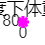

D = 30;
Exercise_Time = 1; %每天的运动时间(小时)
MET = [4,8,12]; %活动强度系数*
weight = 80; %初始体重*
exercise = MET*weight*Exercise_Time; %每天运动消耗的能量
New_Weight = zeros(1,D); %存放每天的体重
New_Weight(1) = weight; %第一天的体重
Intake = 8368; %每天的能量摄入量数组
BMR = 24*4.2*weight; %每天的基础消耗**
SDA = 0.1*BMR; %消化耗能*
C = 35000; %每千克脂肪能量
color = {'r','g','m'};%颜色
labels = {'低活动强度（MET=10）', '中活动强度（MET=20）', '高活动强度（MET=30）'};
figure('Position', [100, 100, 800, 400]); 
hold on;
for i = 1 : length(MET)
    Temp_Weight = zeros(1,D+1);
    Temp_Weight(1) = weight;
    for day = 1 : D
        BMR = 24*4.2*Temp_Weight(day); %更新基础消耗
        exercise = MET(i)*Temp_Weight(day); %更新运动量
        SDA = 0.1*BMR;
        change_weight = (Intake-(BMR+SDA+exercise))/C; %实时体重变化量
        Temp_Weight(day+1) = max(Temp_Weight(day)+change_weight,40); %更新每日体重
    end
    plot(0:D, Temp_Weight,'-*', ...
        'Color', color{i}, 'LineWidth', 1.5, ...
        'MarkerSize', 6, 'MarkerFaceColor', 'w', ...
        'DisplayName', labels{i});
end
grid on;
xlabel('时间(天)');
ylabel('体重(kg)');
title('不同活动强度下体重的变换情况');